# Descriptive statistics feature extraction

function out = descFeat(input, varargin)

## Value assignment and input investigiation

plottingIsOn = 0;
trimPercentage = 10;

if istable(input)
    input = table2array(input);
end

if isnan(input)
    warning("There is at least one NaN in the input array. _wrrNaN" );
end
if isinf(input)
    warning("There is at least one Inf value in the input array. _wrrInf" );
end


## Calculation

### Measures of Central Tendency

Arithmetic mean:

out.mean = mean(input, "omitnan");

Trimmed mean (mean, excluding outliers):

out.trimmean = trimmean(input, trimPercentage);

Geometric mean: $\left(\prod _{i=1}^{n}x_{i}\right)^{\frac {1}{n}}={\sqrt[{n}]{x_{1}x_{2}\cdots x_{n}}}$

try
%     out.geomean = geomean(input, "omitnan");
catch
    % an error occured
end

Harmonic mean: In mathematics, the harmonic mean (sometimes called the subcontrary mean) is one of several kinds of average, and in particular one of the Pythagorean means. Typically, it is appropriate for situations when the average of rates is desired. [Wikipedia]


$$H = \frac{n}{\sum_{i=1}^{n} \frac{1}{x_i}$$


out.harmmean = harmmean(input, "omitnan");

Median (middle) value:

out.median = median(input, "omitnan");

Most frequent value:

out.mode = mode(input);

### Measures of Spread

Range of values (largest – smallest)

out.min = min(input);
out.max = max(input);
out.range = range(input);

Standard deviation: $\sigma = \sqrt{\frac{1}{N-1}\sum_{i=1}^N (x_i - \bar{x})^2 }$ 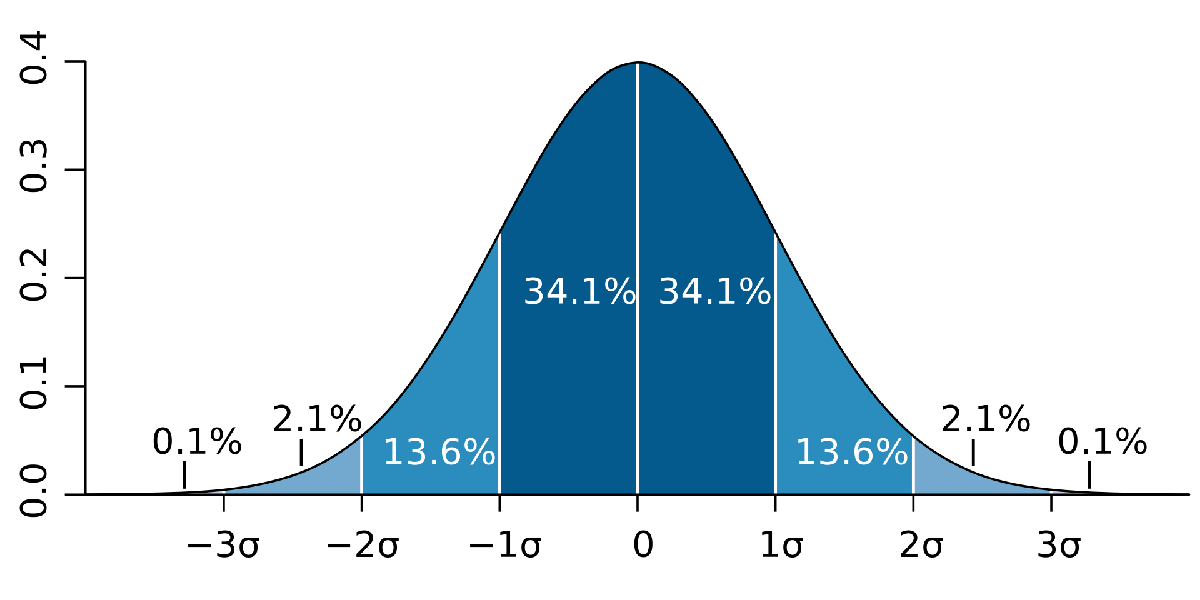

out.std = std(input, "omitnan");

Variance: $\sigma^2$

out.var = var(input, "omitnan");

Mean absolute deviation: the average of the absolute deviations or the positive difference of the given data and that certain value (generally central values). 

out.meanad = mad(input);

Median absolute deviation: 

out.medad = mad(input,1);

Interquartile range: difference between the 75th and the 25th percentiles of the data contained in `x. `

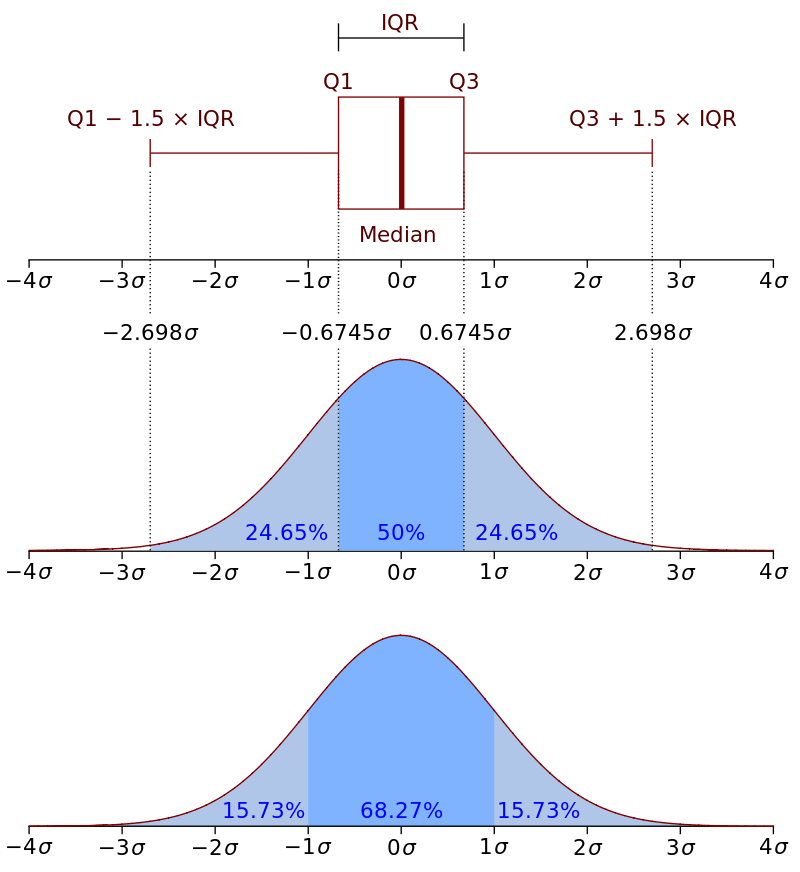

out.iqr = iqr(input);

### Measures of Shape

Skewness: $\tilde{\mu}_3 = {E}\left[\left(\frac{X-\mu}{\sigma}\right)^3 \right]$

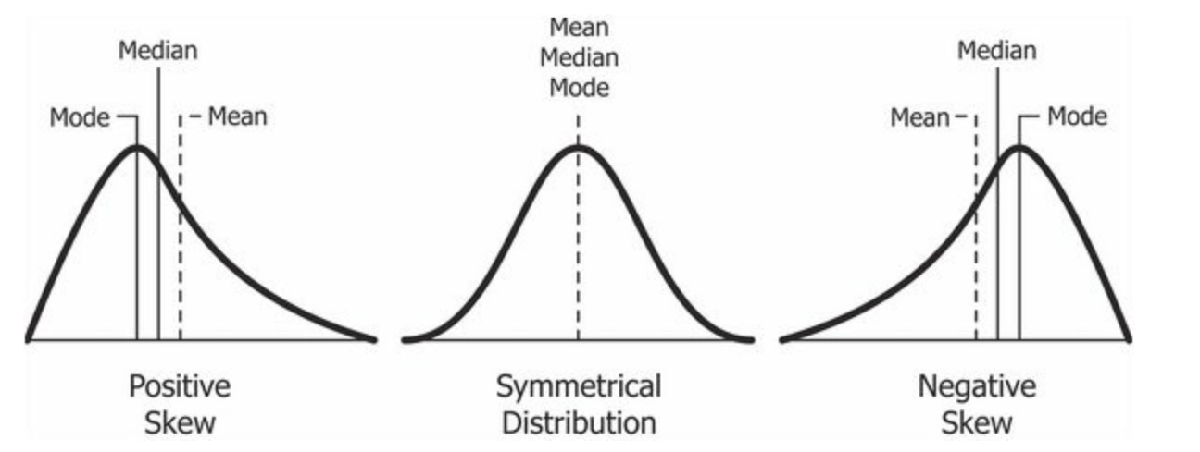

out.skewness = skewness(input);

Kurtosis: is a measure of the "tailedness" of the probability distribution of a real-valued random variable. Like skewness, kurtosis describes the shape of a probability distribution and, like skewness, there are different ways of quantifying it for a theoretical distribution and corresponding ways of estimating it from a sample from a population

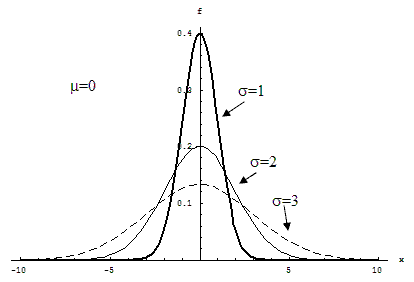

out.kurtosis = kurtosis(input);
% dsOut.moment = moment(input);

### Measure of Normality

`chi2gof` compares the value of the test statistic to a chi-square distribution with degrees of freedom equal to *nbins - 1 - nparams*, where *nbins* is the number of bins used for the data pooling and nparams is the number of estimated parameters used to determine the expected counts. If there are not enough degrees of freedom to conduct the test, `chi2gof` returns the *p*-value as `NaN`.

The chi-square goodness-of-fit test determines if a data sample comes from a specified probability distribution, with parameters estimated from the data.

The test groups the data into bins, calculating the observed and expected counts for those bins, and computing the chi-square test statistic


$$\chi^2 = \sum_{i=1}^n {\frac{(O_i - E_i)}{E_i}^2}$$


[~,p] = chi2gof(input);
out.chi = p;

[~, p] = kstest(input);
out.kstest = p;

## Plotting

% if plottingIsOn
%     tendency = ["Mean", "Median", "Mode", "Trimmed Mean", "Geometric Mean", "Harmonic Mean"];
%     spread = ["Range", "Standard Deviation", ]
%     arr = struct2array(out);
%     
%     fig1 = figure;
%     hold on
%     for i = 1:length(tendency)
%         plot(arr(i), 0, '+ blue');
%         text(arr(i), 0, tendency(i),'VerticalAlignment','bottom','HorizontalAlignment','center');
%     end
% end

end